# Symbolic calculation of the Jacobian matrix of the manipulator ABB IRB120.

## **Part 1: Obtain the Geometric Jacobian of the IRB120 manipulator**

### Direct** Kinematic Model (DKM)**

Firstly, the direct kinematic model of the ABB IRB120 manipulator must be defined. These are the frames assigned to every joint of the manipulator following the Denavit-Hartemberg standard method (DH1):

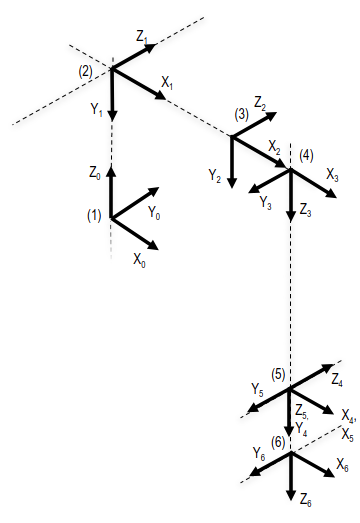

And the following table of Denavit-Hartenberg parameters:

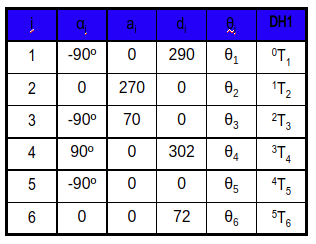

**Note.-** The references for angles in this Direct Kinematic Model (DKM) do not correspond to the IRB120 manufacturer reference frame.

### **Solution.-**

The first step is to declare the symbolic variables: joint variables and Denavit-Hartenberg parameters. We can also create two vectors with the sine and cosine of the articular variables, to simplify matrices construction.

The first step is to compute the homogeneus transform matrices for each pair of jonts along the manipulator, for DH1:

We need matrices form reference from {0] to {6}. Using symbolic computation (using functions available in Virtual Campus):

syms alpha a theta d real
T=despZ(d)*rotZ(theta)*despX(a)*rotX(alpha)

$$T = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Each matrix can be evaluated for each row in the DH1 parameters table:

% Standard Denavit-Hartemberg parameters (DH1)
di=[0.089159 0 0 0.10915 0.09465 0.0823];
ai=[0 -0.425 -0.39225 0 0 0];
alphai=[0 pi/2 0 0 pi/2 -pi/2];
syms q1 q2 q3 q4 q5 q6 phi Xa Ya r a LB real
r=0.25;
a=1.05;
LB=0;
qi=[q1 q2 q3 q4 q5 q6]; 

T01=subs(T,{a,alpha,d,theta},{ai(1),alphai(1),di(1),qi(1)})

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & a\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & a\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & \frac{6424583026827617}{72057594037927936}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12=subs(T,{a,alpha,d,theta},{ai(2),alphai(2),di(2),qi(2)+pi/2}) % aquí he añadido un offset

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}+\frac{\pi }{2}\right) & 0 & \sin\left(q_{2}+\frac{\pi }{2}\right) & a\,\cos\left(q_{2}+\frac{\pi }{2}\right)\\ \sin\left(q_{2}+\frac{\pi }{2}\right) & 0 & -\cos\left(q_{2}+\frac{\pi }{2}\right) & a\,\sin\left(q_{2}+\frac{\pi }{2}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23=subs(T,{a,alpha,d,theta},{ai(3),alphai(3),di(3),qi(3)}) 

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & a\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & a\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34=subs(T,{a,alpha,d,theta},{ai(4),alphai(4),di(4),qi(4)-pi/2}) % aquí he añadido un offset

$$T34 = \left(\begin{array}{cccc} \cos\left(q_{4}-\frac{\pi }{2}\right) & -\sin\left(q_{4}-\frac{\pi }{2}\right) & 0 & a\,\cos\left(q_{4}-\frac{\pi }{2}\right)\\ \sin\left(q_{4}-\frac{\pi }{2}\right) & \cos\left(q_{4}-\frac{\pi }{2}\right) & 0 & a\,\sin\left(q_{4}-\frac{\pi }{2}\right)\\ 0 & 0 & 1 & \frac{2183}{20000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45=subs(T,{a,alpha,d,theta},{ai(5),alphai(5),di(5),qi(5)}) 

$$T45 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & 0 & \sin\left(q_{5}\right) & a\,\cos\left(q_{5}\right)\\ \sin\left(q_{5}\right) & 0 & -\cos\left(q_{5}\right) & a\,\sin\left(q_{5}\right)\\ 0 & 1 & 0 & \frac{1893}{20000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T56=subs(T,{a,alpha,d,theta},{ai(6),alphai(6),di(6),qi(6)})

$$T56 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & 0 & -\sin\left(q_{6}\right) & a\,\cos\left(q_{6}\right)\\ \sin\left(q_{6}\right) & 0 & \cos\left(q_{6}\right) & a\,\sin\left(q_{6}\right)\\ 0 & -1 & 0 & \frac{823}{10000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Then, the matrix from {0} to {6} of the DKM can be computed (and the rest of matrices to every joint form frame {0}):

%T01 computed before.
T02=simplify(T01*T12)

$$T02 = \left(\begin{array}{cccc} -\sin\left(q_{1}+q_{2}\right) & 0 & \cos\left(q_{1}+q_{2}\right) & -a\,\left(\sin\left(q_{1}+q_{2}\right)-\cos\left(q_{1}\right)\right)\\ \cos\left(q_{1}+q_{2}\right) & 0 & \sin\left(q_{1}+q_{2}\right) & a\,\left(\cos\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 & 1 & 0 & \frac{6424583026827617}{72057594037927936}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03=simplify(T02*T23)

$$T03 = \left(\begin{array}{cccc} -\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right) & \sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}+q_{2}\right) & -a\,\left(\sin\left(q_{1}+q_{2}\right)-\cos\left(q_{1}\right)\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\\ \cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right) & -\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}+q_{2}\right) & a\,\left(\cos\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & a\,\sin\left(q_{3}\right)+\frac{6424583026827617}{72057594037927936}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T04=simplify(T03*T34)

$$T04 = \left(\begin{array}{cccc} -\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right) & -\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & \frac{2183\,\cos\left(q_{1}+q_{2}\right)}{20000}-a\,\sin\left(q_{1}+q_{2}\right)+a\,\cos\left(q_{1}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right) & \cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}+q_{4}\right) & \sin\left(q_{1}+q_{2}\right) & \frac{2183\,\sin\left(q_{1}+q_{2}\right)}{20000}+a\,\cos\left(q_{1}+q_{2}\right)+a\,\sin\left(q_{1}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\\ -\cos\left(q_{3}+q_{4}\right) & \sin\left(q_{3}+q_{4}\right) & 0 & a\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)+\frac{6424583026827617}{72057594037927936}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T05=simplify(T04*T45)

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{2}\,\sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & \sigma_{1}\,\sin\left(q_{1}+q_{2}\right) & \frac{1019\,\cos\left(q_{1}+q_{2}\right)}{5000}-a\,\sin\left(q_{1}+q_{2}\right)+a\,\cos\left(q_{1}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{5}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ \sigma_{2}\,\cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & -\sigma_{1}\,\cos\left(q_{1}+q_{2}\right) & \frac{1019\,\sin\left(q_{1}+q_{2}\right)}{5000}+a\,\cos\left(q_{1}+q_{2}\right)+a\,\sin\left(q_{1}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{5}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ -\sigma_{1} & 0 & -\sigma_{2} & a\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)-a\,\sigma_{1}+\frac{6424583026827617}{72057594037927936}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}+q_{4}+q_{5}\right)\\ \sigma_{2}=\sin\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

T06=simplify(T05*T56)

### Jacobian matrix

Compute the Jacobian matrix of the IRB120 manipulator referenced to the base frame using the geometric method.

In order to build the Jacobian matrix we need the vectors z_i (the z vectors of the reference frames), and the vectors p_i (the position vectors of the origins of the reference frames). Attention, must be referenced to the system {0}. We have to use the matrices that we have found in the previous step, in the DKM. For z_i vectors we use the corresponding rotation matrix and p_i vectors are the position part of the homogeneus transformations matrices (position vectors of the origin of the corresponding frames).

%joint vectors (zi)
zL=[0 0 1]';
z0=zL

z0 =      0
     0
     1


z1=T01(1:3,1:3)*zL

$$z1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

z2=T02(1:3,1:3)*zL

$$z2 = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)\\ 0 \end{array}\right)$$

z3=T03(1:3,1:3)*zL

$$z3 = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)\\ 0 \end{array}\right)$$

z4=T04(1:3,1:3)*zL

$$z4 = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)\\ 0 \end{array}\right)$$

z5=T05(1:3,1:3)*zL

$$z5 = \left(\begin{array}{c} \cos\left(q_{3}+q_{4}+q_{5}\right)\,\sin\left(q_{1}+q_{2}\right)\\ -\cos\left(q_{3}+q_{4}+q_{5}\right)\,\cos\left(q_{1}+q_{2}\right)\\ -\sin\left(q_{3}+q_{4}+q_{5}\right) \end{array}\right)$$

 
%position vectors (pi); they are the position part of the homogeneus
%transformation matrices (position of the origin of the reference frame)
p0=[0 0 0]';
p1=T01(1:3,4)

$$p1 = \left(\begin{array}{c} a\,\cos\left(q_{1}\right)\\ a\,\sin\left(q_{1}\right)\\ \frac{6424583026827617}{72057594037927936} \end{array}\right)$$

p2=T02(1:3,4)

$$p2 = \left(\begin{array}{c} -a\,\left(\sin\left(q_{1}+q_{2}\right)-\cos\left(q_{1}\right)\right)\\ a\,\left(\cos\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ \frac{6424583026827617}{72057594037927936} \end{array}\right)$$

p3=T03(1:3,4)

$$p3 = \left(\begin{array}{c} -a\,\left(\sin\left(q_{1}+q_{2}\right)-\cos\left(q_{1}\right)\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\\ a\,\left(\cos\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\\ a\,\sin\left(q_{3}\right)+\frac{6424583026827617}{72057594037927936} \end{array}\right)$$

p4=T04(1:3,4)

$$p4 = \left(\begin{array}{c} \frac{2183\,\cos\left(q_{1}+q_{2}\right)}{20000}-a\,\sin\left(q_{1}+q_{2}\right)+a\,\cos\left(q_{1}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\\ \frac{2183\,\sin\left(q_{1}+q_{2}\right)}{20000}+a\,\cos\left(q_{1}+q_{2}\right)+a\,\sin\left(q_{1}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\\ a\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)+\frac{6424583026827617}{72057594037927936} \end{array}\right)$$

p5=T05(1:3,4)

$$p5 = \left(\begin{array}{c} \frac{1019\,\cos\left(q_{1}+q_{2}\right)}{5000}-a\,\sin\left(q_{1}+q_{2}\right)+a\,\cos\left(q_{1}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{5}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ \frac{1019\,\sin\left(q_{1}+q_{2}\right)}{5000}+a\,\cos\left(q_{1}+q_{2}\right)+a\,\sin\left(q_{1}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{5}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ a\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)-a\,\cos\left(q_{3}+q_{4}+q_{5}\right)+\frac{6424583026827617}{72057594037927936} \end{array}\right)$$

p6=T06(1:3,4)

$$p6 = \begin{array}{l} \left(\begin{array}{c} \frac{1019\,\cos\left(q_{1}+q_{2}\right)}{5000}+\frac{823\,\sigma_{1}\,\sin\left(q_{1}+q_{2}\right)}{10000}-a\,\sin\left(q_{1}+q_{2}\right)+a\,\cos\left(q_{1}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\sigma_{2}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)-a\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{5}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ \frac{1019\,\sin\left(q_{1}+q_{2}\right)}{5000}-\frac{823\,\sigma_{1}\,\cos\left(q_{1}+q_{2}\right)}{10000}+a\,\cos\left(q_{1}+q_{2}\right)+a\,\sin\left(q_{1}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)+a\,\sigma_{2}\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{5}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ a\,\sin\left(q_{3}\right)-a\,\cos\left(q_{3}+q_{4}\right)-\frac{823\,\sigma_{2}}{10000}-a\,\sigma_{1}-a\,\sigma_{1}\,\cos\left(q_{6}\right)+\frac{6424583026827617}{72057594037927936} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}+q_{4}+q_{5}\right)\\ \sigma_{2}=\sin\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

The last step is to build the Jacobian matrix, which in this case (all joint are revolute) corresponds to:


$$J(q)=\left[ {\begin{array}{cccc} z_0 \times (p_6-p_0) & z_1 \times (p_6-p_1) & z_2 \times (p_6-p_2) & z_3 \times (p_6-p_3) & z_4 \times (p_6-p_4) & z_5 \times (p_6-p_5) \\ z_0 & z_1 & z_2 & z_3 & z_4 & z_5 \end{array} } \right]$$


We can compute the matrix by columns (J1, J2, J3, J4, J5 and J6), where each column is composed by the definition. E.g., J1 would be:

J1=[cross(z0,(p6(1:3)-p0(1:3)));z0];

%Columns according to the algorithm (J=[JP;JO]); we are left with the three
%first elements of each pi vector
J1=simplify([cross(z0,(p6-p0));z0])

$$J1 = \begin{array}{l} \left(\begin{array}{c} \frac{823\,\sigma_{2}\,\cos\left(q_{1}+q_{2}\right)}{10000}-\frac{1019\,\sin\left(q_{1}+q_{2}\right)}{5000}-a\,\cos\left(q_{1}+q_{2}\right)-a\,\sin\left(q_{1}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\sigma_{1}\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{5}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ \frac{1019\,\cos\left(q_{1}+q_{2}\right)}{5000}+\frac{823\,\sigma_{2}\,\sin\left(q_{1}+q_{2}\right)}{10000}-a\,\sin\left(q_{1}+q_{2}\right)+a\,\cos\left(q_{1}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\sigma_{1}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)-a\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{5}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{3}+q_{4}+q_{5}\right)\\ \sigma_{2}=\cos\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

J2=simplify([cross(z1,(p6-p1));z1])

$$J2 = \begin{array}{l} \left(\begin{array}{c} \frac{823\,\sigma_{2}\,\cos\left(q_{1}+q_{2}\right)}{10000}-\frac{1019\,\sin\left(q_{1}+q_{2}\right)}{5000}-a\,\cos\left(q_{1}+q_{2}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\sigma_{1}\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{5}\right)-a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ \frac{1019\,\cos\left(q_{1}+q_{2}\right)}{5000}+\frac{823\,\sigma_{2}\,\sin\left(q_{1}+q_{2}\right)}{10000}-a\,\sin\left(q_{1}+q_{2}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)+a\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{4}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)-a\,\sigma_{1}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)-a\,\cos\left(q_{3}+q_{4}\right)\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{5}\right)-a\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}+q_{4}\right)\,\cos\left(q_{5}\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{3}+q_{4}+q_{5}\right)\\ \sigma_{2}=\cos\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

J3=simplify([cross(z2,(p6-p2));z2])

$$J3 = \begin{array}{l} \left(\begin{array}{c} -\sin\left(q_{1}+q_{2}\right)\,\sigma_{1}\\ \cos\left(q_{1}+q_{2}\right)\,\sigma_{1}\\ \frac{a\,\sin\left(q_{3}+q_{4}+q_{5}+q_{6}\right)}{2}-\frac{823\,\sigma_{2}}{10000}+a\,\sin\left(q_{3}+q_{4}\right)+a\,\cos\left(q_{3}\right)+\frac{a\,\sin\left(q_{3}+q_{4}+q_{5}-q_{6}\right)}{2}+a\,\sigma_{3}\\ \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{823\,\sigma_{3}}{10000}+a\,\cos\left(q_{3}+q_{4}\right)-a\,\sin\left(q_{3}\right)+a\,\sigma_{2}+a\,\sigma_{2}\,\cos\left(q_{6}\right)\\ \sigma_{2}=\cos\left(q_{3}+q_{4}+q_{5}\right)\\ \sigma_{3}=\sin\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

J4=simplify([cross(z3,(p6-p3));z3])

$$J4 = \begin{array}{l} \left(\begin{array}{c} -\sin\left(q_{1}+q_{2}\right)\,\sigma_{1}\\ \cos\left(q_{1}+q_{2}\right)\,\sigma_{1}\\ \frac{a\,\sin\left(q_{3}+q_{4}+q_{5}+q_{6}\right)}{2}-\frac{823\,\sigma_{2}}{10000}+a\,\sin\left(q_{3}+q_{4}\right)+\frac{a\,\sin\left(q_{3}+q_{4}+q_{5}-q_{6}\right)}{2}+a\,\sin\left(q_{3}+q_{4}+q_{5}\right)\\ \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{823\,\sin\left(q_{3}+q_{4}+q_{5}\right)}{10000}+a\,\cos\left(q_{3}+q_{4}\right)+a\,\sigma_{2}+a\,\sigma_{2}\,\cos\left(q_{6}\right)\\ \sigma_{2}=\cos\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

J5=simplify([cross(z4,(p6-p4));z4])

$$J5 = \begin{array}{l} \left(\begin{array}{c} -\sin\left(q_{1}+q_{2}\right)\,\sigma_{1}\\ \cos\left(q_{1}+q_{2}\right)\,\sigma_{1}\\ \frac{a\,\sin\left(q_{3}+q_{4}+q_{5}+q_{6}\right)}{2}-\frac{823\,\cos\left(q_{3}+q_{4}+q_{5}\right)}{10000}+\frac{a\,\sin\left(q_{3}+q_{4}+q_{5}-q_{6}\right)}{2}+a\,\sin\left(q_{3}+q_{4}+q_{5}\right)\\ \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{823\,\sin\left(q_{3}+q_{4}+q_{5}\right)}{10000}+a\,\cos\left(q_{3}+q_{4}+q_{5}\right)+a\,\cos\left(q_{3}+q_{4}+q_{5}\right)\,\cos\left(q_{6}\right) \end{array}$$

J6=simplify([cross(z5,(p6-p5));z5])

$$J6 = \begin{array}{l} \left(\begin{array}{c} a\,\left(\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)+\sigma_{1}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)\right)\\ a\,\left(\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{6}\right)-\sigma_{1}\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{6}\right)\right)\\ a\,\sigma_{2}\,\sin\left(q_{6}\right)\\ \sigma_{2}\,\sin\left(q_{1}+q_{2}\right)\\ -\sigma_{2}\,\cos\left(q_{1}+q_{2}\right)\\ -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{3}+q_{4}+q_{5}\right)\\ \sigma_{2}=\cos\left(q_{3}+q_{4}+q_{5}\right) \end{array}$$

Finally, the Jacobian matrix is built. A reduced Jacobian matrix can also be defined, in which we eliminate the null rows or columns, which do not contribute to the transition from joint velocities to Cartesian velocities.

JPO=simplify([J1 J2 J3 J4 J5 J6])

% onesJPO=1
Tga=[cos(phi) -sin(phi) 0 0 0 0; sin(phi) cos(phi) 0 0 0 0; 0 0 1 0 0 0; 0 0 0 cos(phi) -sin(phi) 0; 0 0 0 sin(phi) cos(phi) 0; 0 0 0 0 0 1] % He añadido en la parte de Za un 1, como offset de 1 metro

$$Tga = \left(\begin{array}{cccccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & 0 & 0 & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ 0 & 0 & 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

JPOFMM=mtimes(Tga, JPO)


Jmobile=[(r/2)*cos(phi)+((r*LB)/(2*a))*sin(phi) (r/2)*cos(phi)-((r*LB)/(2*a))*sin(phi); (r/2)*sin(phi)-((r*LB)/(2*a))*cos(phi) (r/2)*sin(phi)+((r*LB)/(2*a))*cos(phi); 0 0; 0 0; 0 0; -(r/(2*a)) r/(2*a)]

$$Jmobile = \left(\begin{array}{cc} \frac{\cos\left(\varphi \right)}{8} & \frac{\cos\left(\varphi \right)}{8}\\ \frac{\sin\left(\varphi \right)}{8} & \frac{\sin\left(\varphi \right)}{8}\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ -\frac{5}{42} & \frac{5}{42} \end{array}\right)$$


JacobianMM=[JPOFMM Jmobile]

En este punto, es preferible evaluar la Jacobiana antes de calcular la pseudo-inversa:

Variables

syms qL qR real
%qi=[q1 q2 q3 q4 q5 q6]; 


Positions (adding two positions at the end for theta_L and theta_R):

q=[0 0 0 0 0 0 0 0 0]';

and the joint velocities (adding two velicities at the end for d_theta_L and d_theta_R):

qv=[0.5 0.1 0.4 0.7 0.1 0.5 0.5 0.5]';

Firstly, the Jacobian matrix must be evaluated in the robot configuration:

JacobianMM_num=subs(JacobianMM,{q1,q2,q3,q4,q5,q6,qL,qR},{q(1),q(2),q(3),q(4),q(5),q(6),q(7),q(8)})

$$JacobianMM\_num = \begin{array}{l} \left(\begin{array}{cccccccc} -\sin\left(\varphi \right)\,\left(a+\frac{1019}{5000}\right)-\cos\left(\varphi \right)\,\sigma_{1} & -\frac{1019\,\sin\left(\varphi \right)}{5000}-\cos\left(\varphi \right)\,\sigma_{1} & \sigma_{2} & \sigma_{2} & -2\,a\,\sin\left(\varphi \right) & a\,\cos\left(\varphi \right) & \frac{\cos\left(\varphi \right)}{8} & \frac{\cos\left(\varphi \right)}{8}\\ \cos\left(\varphi \right)\,\left(a+\frac{1019}{5000}\right)-\sin\left(\varphi \right)\,\sigma_{1} & \frac{1019\,\cos\left(\varphi \right)}{5000}-\sin\left(\varphi \right)\,\sigma_{1} & \sigma_{3} & \sigma_{3} & 2\,a\,\cos\left(\varphi \right) & a\,\sin\left(\varphi \right) & \frac{\sin\left(\varphi \right)}{8} & \frac{\sin\left(\varphi \right)}{8}\\ 0 & 0 & a-\frac{823}{10000} & -\frac{823}{10000} & -\frac{823}{10000} & 0 & 0 & 0\\ 0 & 0 & \cos\left(\varphi \right) & \cos\left(\varphi \right) & \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & 0\\ 0 & 0 & \sin\left(\varphi \right) & \sin\left(\varphi \right) & \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & 0\\ 1 & 1 & 0 & 0 & 0 & 0 & -\frac{5}{42} & \frac{5}{42} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,a-\frac{823}{10000}\\ \sigma_{2}=-3\,a\,\sin\left(\varphi \right)\\ \sigma_{3}=3\,a\,\cos\left(\varphi \right) \end{array}$$

And then, the pseudo-inverse can be calculated numerically: 

JacobianInverse=pinv(JacobianMM_num)


%JPOv1=[JPO(1:3,1); onesJPO]
% JPOv2=[JPO(1:3,2); onesJPO]
% JPOv3=[JPO(1:3,3); onesJPO]
% JPOv4=[JPO(1:3,4); onesJPO]
% JPOv5=[JPO(1:3,5); onesJPO]
% JPOv6=[JPO(1:3,6); onesJPO]
% 
% JPOv1n=mtimes(Tga,JPOv1)
% JPOv2n=mtimes(Tga, JPOv2)
% JPOv3n=mtimes(Tga, JPOv3)
% JPOv4n=mtimes(Tga, JPOv4)
% JPOv5n=mtimes(Tga, JPOv5)
% JPOv6n=mtimes(Tga, JPOv6)

% Compute the full Jacobian of lineal velocities

% JPOV=[JPOv1n JPOv2n JPOv3n JPOv4n JPOv5n JPOv6n]

% This matrix has the last row filled with ones, so the next step is to
% remove it.

% JPOV(4,:)=[]

% Have to do the same with the anguar velocities

% JPOw1=[JPO(4:6,1); onesJPO]
% JPOw2=[JPO(4:6,2); onesJPO]
% JPOw3=[JPO(4:6,3); onesJPO]
% JPOw4=[JPO(4:6,4); onesJPO]
% JPOw5=[JPO(4:6,5); onesJPO]
% JPOw6=[JPO(4:6,6); onesJPO]
% 
% JPOw1n=mtimes(Tga, JPOw1)
% JPOw2n=mtimes(Tga, JPOw2)
% JPOw3n=mtimes(Tga, JPOw3)
% JPOw4n=mtimes(Tga, JPOw4)
% JPOw5n=mtimes(Tga, JPOw5)
% JPOw6n=mtimes(Tga, JPOw6)
% 
% JPOW=[JPOw1n JPOw2n JPOw3n JPOw4n JPOw5n JPOw6n]
% 
% JPOW(4,:)=[]

% So right now, to obtain the full Jacobian, of 6x6 expressed with respect
% the global refernce system, we have to join the JPOV and JPOW

% JPOFMM=[JPOV; JPOW]


## Part 2: Compute the Cartesian and                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            velocities of the end-effector

Given a robot configuration:

q=[0 0 0 0 0 0 0]';

and the joint velocities:

qv=[0.5 0.1 0.4 0.7 0.1 0.5]';

Firstly, the Jacobian matrix must be evaluated in the robot configuration:

Jq=subs(JPO,{q1,q2,q3,q4,q5,q6},{q(1),q(2),q(3),q(4),q(5),q(6)})

$$Jq = \left(\begin{array}{cccccc} \frac{823}{10000}-2\,a & \frac{823}{10000}-2\,a & 0 & 0 & 0 & a\\ a+\frac{1019}{5000} & \frac{1019}{5000} & 3\,a & 3\,a & 2\,a & 0\\ 0 & 0 & a-\frac{823}{10000} & -\frac{823}{10000} & -\frac{823}{10000} & 0\\ 0 & 0 & 1 & 1 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & -1\\ 1 & 1 & 0 & 0 & 0 & 0 \end{array}\right)$$

And then, the end-effector velocities in that situation can be computed from:

ve=double(Jq*qv)

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs'
function first to substitute values for variables.

Error in sym/double (line 872)
        Xstr = mupadmex('symobj::double', S.s, 0);

Related documentation